# Pro studenty RIR - poklady pro zápočtový příklad

## J. Kovar

Used literature:

[1] [https://wilselby.com/research/arducopter/controller-design/](https://wilselby.com/research/arducopter/controller-design/) [online 1.12.2023]

[2] Position control of an Unmaned Aerial Vehicle From a Mobile Ground Vehicle; Tiwari, A., PhD thesis,  [https://digitalcommons.mtu.edu/cgi/viewcontent.cgi?article=1528&context=etdr](https://digitalcommons.mtu.edu/cgi/viewcontent.cgi?article=1528&context=etdr)  [online 1.12.2023]

[3] Matlab - drone simulation: [https://www.mathworks.com/discovery/drone-simulation.html](https://www.mathworks.com/discovery/drone-simulation.html) [online 1.12.2023]

The general structure of the control part of the quadrupter is:

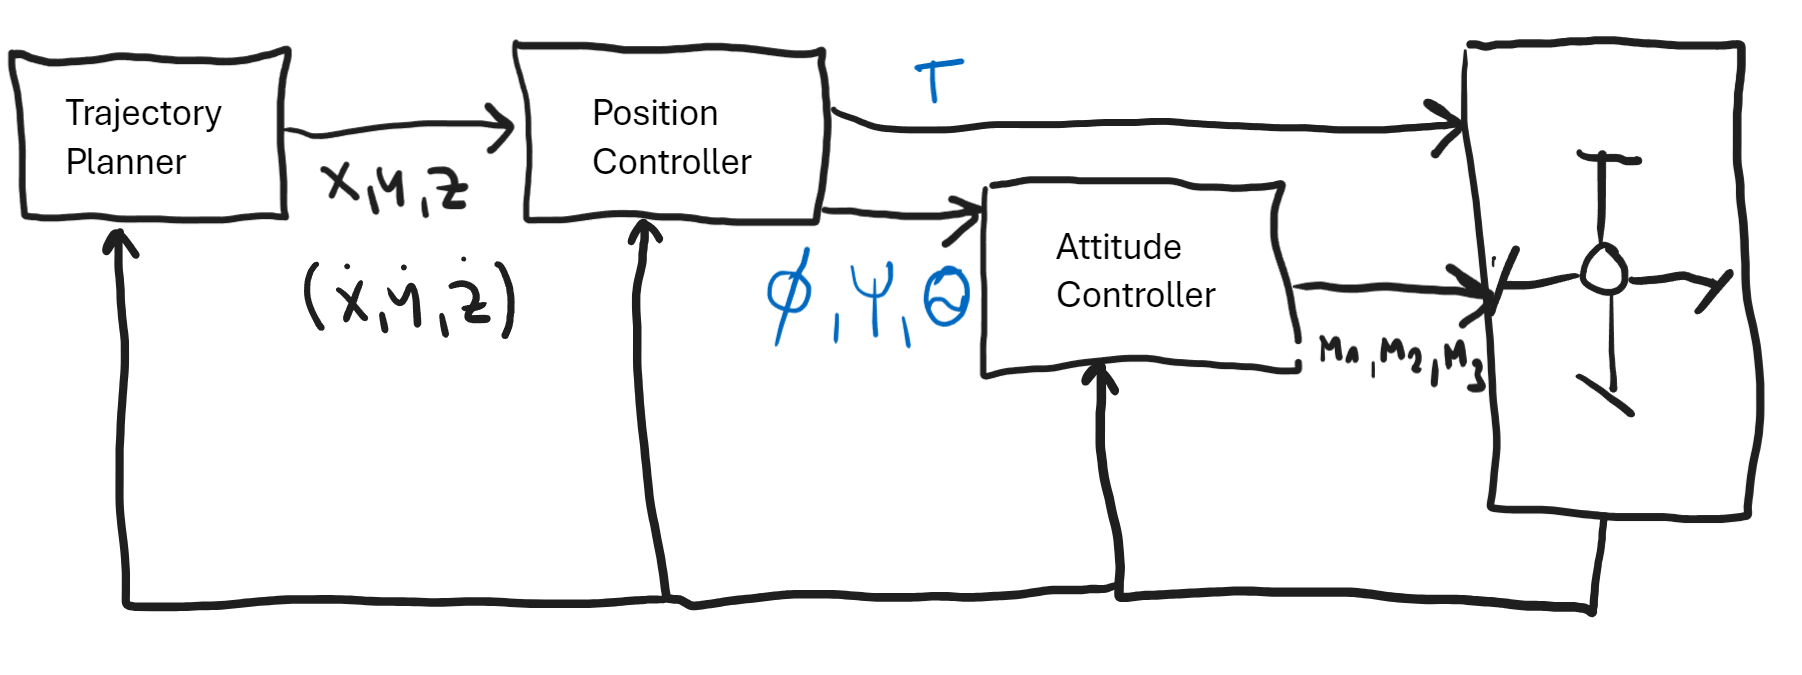

### Explanatory notes

Equation of movement can be found in example [1,2]

Basis:

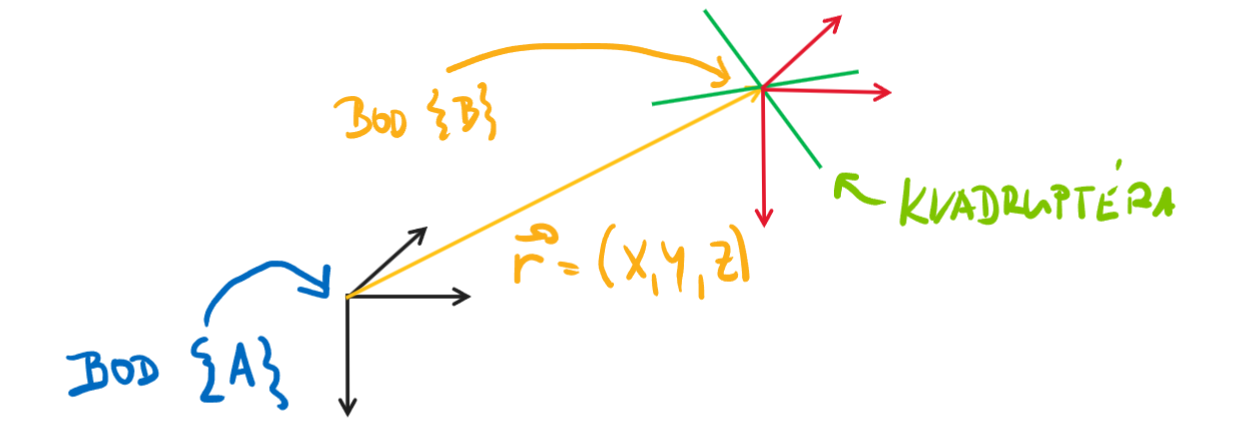

#### Parameters

**(theta) = Pitch (Euler) angle** *(in model obj.parameters.BodyEulerAngle.Theta)*

**(phi) = Roll (Euler) angle** *(in model obj.parameters.BodyEulerAngle.Phi)*

**(psi) = Yaw (Euler) angle** *(in model obj.parameters.BodyEulerAngle.Psi)*

***Angular velocity of quadropter in {B} with respect to {A} - definition in {B} (aka angular rates in the body frame)**** - (in model obj.parameters.BodyAngularRate.dPhi, obj.parameters.BodyAngularRate.dTheta,obj.parameters.BodyAngularRate.dPsi) *

***Location of an quadcopter expressed in {A} (likewise velocity)**** - obj.parameters.BodyXYZPosition.X (Y, Z)*

*NOTE: relation of moments (moments acting on the body fixed frame in point B) as actions to angular rates can be found in line 76 of file Quadcopter.m*

***Inertia matrix expressed in {B} - fixed frame - ****obj.physicalParameters.I *

### Trajectory planner

In the simplest form, the trajectory planner can be implemented as a function that determines the position of the quadrupter in space as a function of time:

format compact;

timeForWaypoints = [0;10;20;30;40];
trajectoryWaypoints = [0 0 0;
                       1 1 1;
                       2 2 2;
                       3 3 3]

trajectoryWaypoints =      0     0     0
     1     1     1
     2     2     2
     3     3     3



deltaT = 0.1;
for i = 0:deltaT:max(timeForWaypoints)
    for j = 2:length(timeForWaypoints)
        if (discretize(i, [timeForWaypoints(j-1),timeForWaypoints(j)]) == 1)
            fprintf("Actual time: %3.2f Waypoint-X: %3.2f Waypoint-Y: %3.2f Waypoint-Z: %3.2f \n", i, trajectoryWaypoints(j-1,1),trajectoryWaypoints(j-1,2),trajectoryWaypoints(j-1,3));
        end
    end
end

Actual time: 0.00 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.10 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.20 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.30 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.40 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.50 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.60 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.70 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.80 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 0.90 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 1.00 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 1.10 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 1.20 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 1.30 Waypoint-X: 0.00 Waypoint-Y: 0.00 Waypoint-Z: 0.00 
Actual time: 1.40 Wa

### Position controller

It is important to note that altitude control can maintain a stable hover of the quadrotor, but has no effect on the translational motion of the quadrotor (airflow is not considered). The translational motion of the quadrupter is provided by "tilting" the entire quadrupter (not rotating the quadrupter about the vertical axis).

See e.g. [1]

In simplest definition - if i want to move quadcopter along X-axis, than roll angle must be modified by regulator:

RollAction = ***PID****(Xdesired - Xactual)*

### Attitude controller

The Attitude controller in its simplest form can be made up of four PID controllers that work as follows:

*TotalThrustCommand = massOfQuadrupter * g - ****PID****(Z'command - Z'actual)*

*M1 = ****PID****(PhiCommand - PhiActual);*

*M2 a M3 likewise*